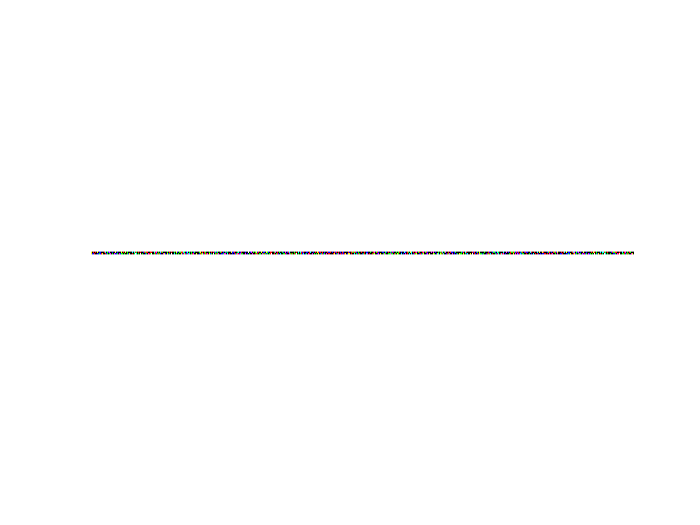

% Defines plainString to be user input
plainString = input("String to encrypt: ","s");
% Pads plainString with spaces until length is evenly divisible by 3
plainString(end+1:ceil(length(plainString)/3)*3) = ' ';
% Sets the increment variable, output array, and alphabets
increment = 0;
outputArray = [];
alphabet = [" ","a","b","c","d","e","f","g","h","i","j","k","l","m","n","o","p","q","r","s","t","u","v","w","x","y","z"];
ternAlphabet = {[0,0;0,0;0,0],[0,0;0,0;0,1],[0,0;0,0;1,0],[0,0;0,1;0,0],[0,0;0,1;0,1],[0,0;0,1;1,0],[0,0;1,0;0,0],[0,0;1,0;0,1],[0,0;1,0;1,0],[0,1;0,0;0,0],[0,1;0,0;0,1],[0,1;0,0;1,0],[0,1;0,1;0,0],[0,1;0,1;0,1],[0,1;0,1;1,0],[0,1;1,0;0,0],[0,1;1,0;0,1],[0,1;1,0;1,0],[1,0;0,0;0,0],[1,0;0,0;0,1],[1,0;0,0;1,0],[1,0;0,1;0,0],[1,0;0,1;0,1],[1,0;0,1;1,0],[1,0;1,0;0,0],[1,0;1,0;0,1],[1,0;1,0;1,0]};
% Increments through plainString,
% appending the corresponding ternAlphabet values to red, green, and blue,
% then stacking them all in outputArray
while increment < ceil(length(plainString)/3)*3
    red = ternAlphabet{alphabet==plainString(1+increment)};
    green = ternAlphabet{alphabet==plainString(2+increment)};
    blue = ternAlphabet{alphabet==plainString(3+increment)};
    letterColor = zeros(3,2,3);
    letterColor(:,:,1) = red;
    letterColor(:,:,2) = green;
    letterColor(:,:,3) = blue;
    outputArray = cat(2,outputArray,letterColor);
    increment = increment + 3;
end
% Outputs an square pixel image without axes to rotTern.bmp
image(outputArray)
axis off
axis image

imwrite(outputArray,"rotTern.bmp")